clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);



## Three-step

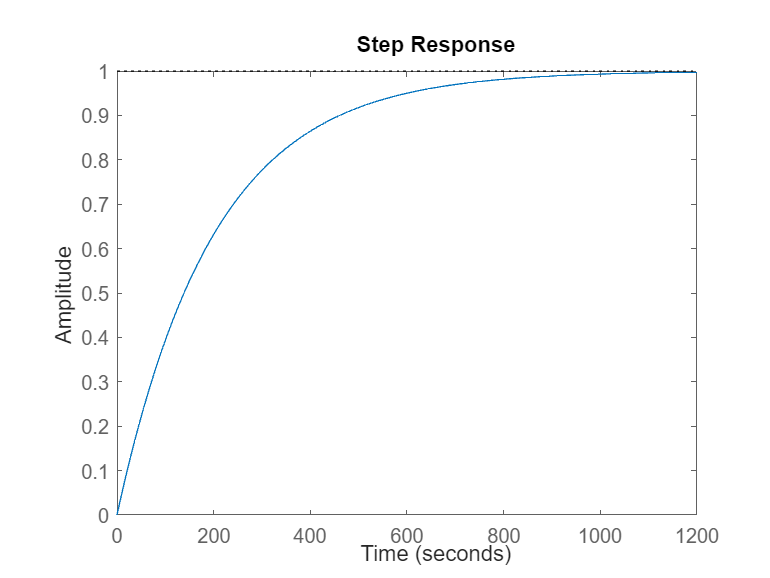

listOfUncertainties = {[-1,1]};
m = length(listOfUncertainties);
Uncertainties = zeros(m,m,m^2);
if(m == 1)% check if the inputs share uncertainties or if they have individual uncertainties
    comb = combinations(cell2mat(listOfUncertainties(1)));
else
    comb = combinations(cell2mat(listOfUncertainties(1)),cell2mat(listOfUncertainties(2)),cell2mat(listOfUncertainties(3)),cell2mat(listOfUncertainties(4)));
end
combDouble = table2array(comb);
for i=1:length(combDouble)
    Uncertainties(:,:,i) = diag(combDouble(i,:));
end
B = @(i) param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd);

s=tf('s');
param.model.Dwz = 20*eye(4);

%Wref
%lowpass filter wich result in a setling time of 10 min.  
wref =eye(4)*(1/(200*s+1));
wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
figure()
step(wref(1,1))


%Wu set to 0 to not take u into the syntehsis procces
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0.1*eye(4);

yalmip('clear')

q = cell(param.n);
y = cell(param.n);
%fill in p^-1
for i = 1:param.n
    q{i} = sdpvar(3);
    y{i} = sdpvar(1,3,'full');
end
% % fill in the rest of p_bar
% for i = 1:4
%     q{param.n+i} = sdpvar(4);
%     y{param.n+i} = sdpvar(4);
% end
Q_hat = sdpvar(28,28); %28x28
% Y_hat = sdpvar(20,28,'full'); %20x28
Y_hat = [sdpvar(4,28,'full')];

%insert Q into Q_hat
Q_hat(1:12,1:12) = blkdiag(q{:});
%insert Y into y_hat
Y_hat(1:4,1:12) = blkdiag(y{:});

gammaRS = sdpvar(1); %(1);
gammaPerformance = sdpvar(1);
gammaDesiredPerformance =sdpvar(1);

%constraints
constriants = [];

%Define the lyapunaov constraint for the decoupled system 
    Lyap = param.model.A * Q_hat(1:param.n*3,1:param.n*3) + Q_hat(1:param.n*3,1:param.n*3) * param.model.A.' + param.model.B_Bar * Y_hat(1:param.n,1:param.n*3) + Y_hat(1:param.n,1:param.n*3).' * param.model.B_Bar.';
    constriants = [constriants, Lyap <= 0, Q_hat(1:param.n*3,1:param.n*3) >= 0];

%Define the parameters for desired response
Cz = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);
Bw = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
Dz = eye(4);

A_hat = [param.model.A, Bw*param.model.Cww, zeros(12,4),zeros(12,4),zeros(12,4);
         zeros(4,12),param.model.Aww, zeros(4),zeros(4),zeros(4);
         param.model.Bwz*Cz, -param.model.Bwz*param.model.DWref*param.model.Cww, param.model.Awz, -param.model.Bwz*param.model.CWref,zeros(4);
         zeros(4,12),param.model.BWref*param.model.Cww, zeros(4),param.model.AWref,zeros(4);
         zeros(4,12), zeros(4),zeros(4),zeros(4),param.model.AWu]; 


B_hat = @(k) [B(k);
             zeros(4,4);
             zeros(4,4);
             zeros(4,4);
             param.model.BWu];

B_bar = [Bw*param.model.Dww;
         param.model.Bww;
         -param.model.Bwz*param.model.DWref*param.model.Dww;
         param.model.BWref*param.model.Dww;
         zeros(4,4)];

C1 = [param.model.Dwz*Cz, -param.model.Dwz*param.model.DWref*param.model.Cww, param.model.Cwz,-param.model.Dwz*param.model.CWref,zeros(4);
      zeros(4,12),zeros(4),zeros(4),zeros(4),param.model.CWu];

C2 = [zeros(4,4);
      param.model.DWu];

D_Bar = [-param.model.Dwz*param.model.DWref*param.model.Dww;
        zeros(4,4);];

constraints = [param.model.A * Q_hat(1:12,1:12) + Q_hat(1:12,1:12) * param.model.A.' + param.model.B_Bar * Y_hat(1:4,1:12) + Y_hat(1:4,1:12).' * param.model.B_Bar.' <=0];
for i=1:length(Uncertainties)
    constraints = [constraints, [Q_hat*A_hat.'+A_hat*Q_hat+Y_hat.'*B_hat(i).'+B_hat(i)*Y_hat, B_bar, Q_hat*C1.'+Y_hat.'*C2.';
                     B_bar.', -gammaDesiredPerformance*eye(4),D_Bar.';
                     C1*Q_hat+C2*Y_hat, D_Bar, -gammaDesiredPerformance*eye(8)]<=0];
end
constraints = [constraints,gammaDesiredPerformance >= 0, Q_hat >=0];

options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints,[gammaDesiredPerformance],options);
disp("gamma desired per")

gamma desired per


value(gammaDesiredPerformance)

ans = 0.0175

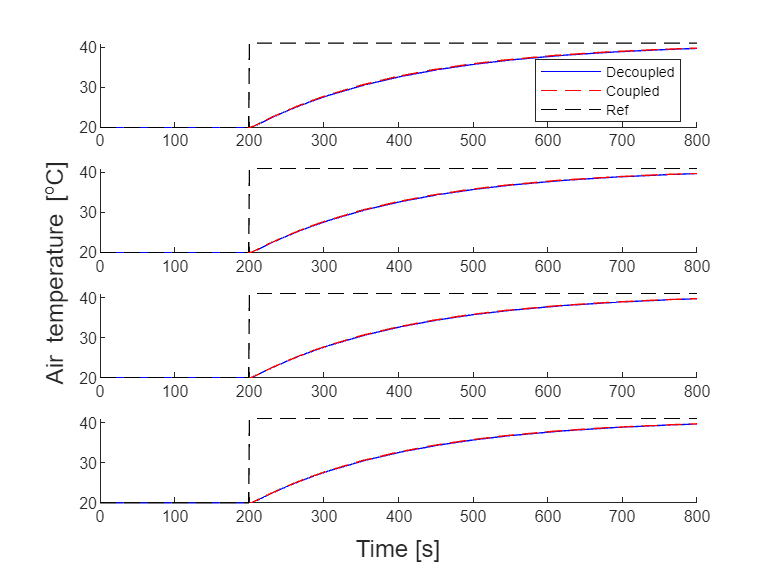

y_out = value(Y_hat);
q_out = value(Q_hat);
Ksf = y_out(1:4,1:12)/q_out(1:12,1:12);

param.ctrl.K = Ksf;
util.SimulateLinearStep(param,"Examination_Output_Feedback_Performance",0,800,21);


% 
% % Step 1-3
A = param.model.A + (0)*eye(12);
% 
% yalmip('clear')
% q = cell(1,param.n);
% y = cell(1,param.n);
% for i=1:param.n
%     q{i} = sdpvar(3);
%     y{i} = sdpvar(1,3,'full');
% end
% Q = blkdiag(q{:});
% Y = blkdiag(y{:});
% 
% % Setup constraint
% constraints = [A * Q + Q * A.' + param.model.B_Bar * Y + Y.' * param.model.B_Bar.' <=0];
% for i=1:length(Uncertainties)
%     constraints = [constraints, A * Q + Q * A.' + param.model.B * (eye(4) + Uncertainties(i) * param.model.Dwd) * Y + Y.' * (eye(4) + Uncertainties(i) * param.model.Dwd)' * param.model.B.' <= 0];
% end
% % constraints = [constraints,  Q - eye(12) >= 0];
% % options = sdpsettings('verbose',0,'solver','mosek');
% % sol = optimize(constraints, trace(Q), options)
% constraints = [constraints,  Q >= 0];
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints, [], options);
% 
% % step 4
% Ksf = value(Y)/value(Q);
% Ksf = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));
% [decoupledResults,coupledResults] = util.SimulateStep(param,"Output_Feedback",0);

%step 5
yalmip('clear')
p = cell(1,param.n);
for i=1:param.n
    p{i} = sdpvar(3);
end
gammaDesiredPerformance = sdpvar(1);
P = sdpvar(28);
P(1:12,1:12) = blkdiag(p{:});
sigma = sdpvar(1);
constraints = [A.'*P(1:12,1:12) + P(1:12,1:12)*A - sigma*(param.model.CySOF.'*param.model.CySOF) <= 0];
for i=1:length(Uncertainties)
    constraints = [constraints, [(A_hat + B_hat(i)*Ksf*[eye(12),zeros(12,16)]).'*P + P*(A_hat + B_hat(i)*Ksf*[eye(12),zeros(12,16)]), P * B_bar, (C1+C2*Ksf*[eye(12),zeros(12,16)]).';
                     B_bar.' * P, -gammaDesiredPerformance*eye(4),D_Bar.';
                     (C1+C2*Ksf*[eye(12),zeros(12,16)]), D_Bar, -gammaDesiredPerformance*eye(8)]<=0];
end
constraints = [constraints, P>=0, sigma >= 0];
% for i=1:length(Uncertainties)
%     constraints = [constraints, (A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*Ksf).'*P(1:12,1:12) + P(1:12,1:12)*(A + param.model.B*(eye(4) + Uncertainties(i) * param.model.Dwd)*Ksf)<=0];
% end
% constraints = [constraints, P(1:12,1:12)>=0, sigma >= 0];
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, [gammaDesiredPerformance], options)

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0493
       solvertime: 0.0907
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


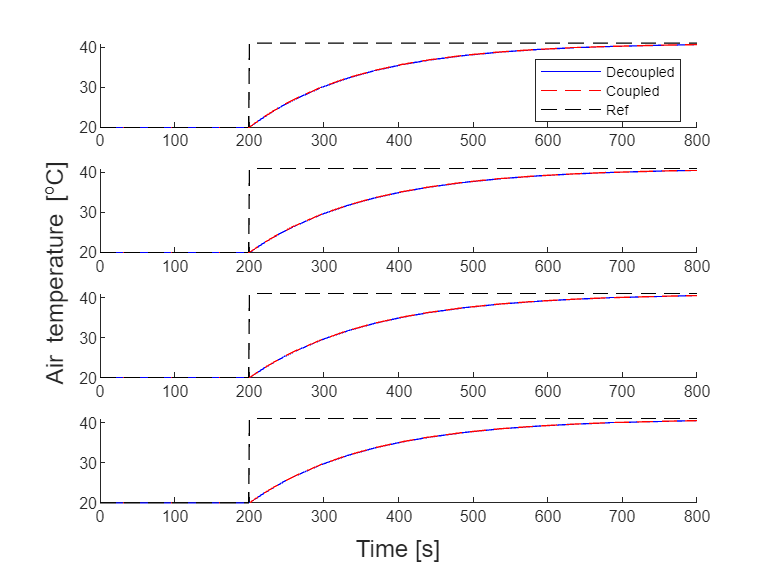


P_min = value(P);

% Step 6
yalmip('clear')
k = cell(1,param.n);
for j=1:param.n
    k{j} = sdpvar(1,2,'full');
end
K = blkdiag(k{:});
% gammaDesiredPerformance = sdpvar(1);
% 
% C_hat = [param.model.CySOF, zeros(8,16)];
% P = P_min
% % P = blkdiag(P(1:12,1:12),eye(16))
% constraints = [];
% % constraints = [param.model.A * Q_hat(1:12,1:12) + Q_hat(1:12,1:12) * param.model.A.' + param.model.B_Bar * Y_hat(1:4,1:12) + Y_hat(1:4,1:12).' * param.model.B_Bar.' <=0];
% for i=1:length(Uncertainties)
%     constraints = [constraints, [(A_hat + B_hat(i)*K*C_hat).'*P + P*(A_hat + B_hat(i)*K*C_hat), P * B_bar, (C1+C2*K*C_hat).';
%                      B_bar.' * P, -gammaDesiredPerformance*eye(4),D_Bar.';
%                      (C1+C2*K*C_hat), D_Bar, -gammaDesiredPerformance*eye(8)]<=0];
% end
% constraints = [constraints,gammaDesiredPerformance >= 0];
% 
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints,[gammaDesiredPerformance],options);
% disp("gamma desired per")
% value(gammaDesiredPerformance)
gamma = sdpvar(1);
    
kvec = [K(:,1);K(:,2);K(:,3);K(:,4);K(:,5);K(:,6);K(:,7);K(:,8)];
constraints = [gamma, kvec.'; kvec, eye(size(kvec,1))]>=0;
    
for i=1:length(Uncertainties)
    constraints = [constraints, [(A + B(i)*K*param.model.CySOF).'*P_min(1:12,1:12) + P_min(1:12,1:12)*(A + B(i)*K*param.model.CySOF)]<=0];
end
options = sdpsettings('verbose',0,'solver','mosek');
sol = optimize(constraints, gamma, options);

Ksof = value(K);

Ks = zeros(1,3,param.n);
for j=1:param.n
    Ks(1,2:3,j) = Ksof(j,2*(j-1)+1:2*j);
end
%saves the block version of K this is used further in some simulations
param.ctrl.K = Ksof*param.model.CySOF;
%saves a 3d matrix version of Ks this is used in the simulation of the
%nonlinear system.
param.ctrl.Ks = Ks;


util.SimulateLinearStep(param,"Examination_Output_Feedback_Performance",0,800,21);

util.CalculatePerformanceLPV(param,{[-1,1]});

Gamma = 20.0168

ActualGamma = 20.0214